clc;
close all;

trainingData = readtable("Train_WO_Aug.csv");
X_Train = trainingData.Name;
validData = readtable("Valid.csv");
testingData = readtable("Test_K1.csv");

Y_Train = trainingData.Value;
Y_Valid = validData.Value;
Y_Test = testingData.Value;
fn = X_Train{1};
size(imread(fn));
%imshow(imread(fn));

%augmenter = imageDataAugmenter('RandRotation',[-20,20], 'RandXTranslation',[-5 5],'RandYTranslation',[-5 5]);

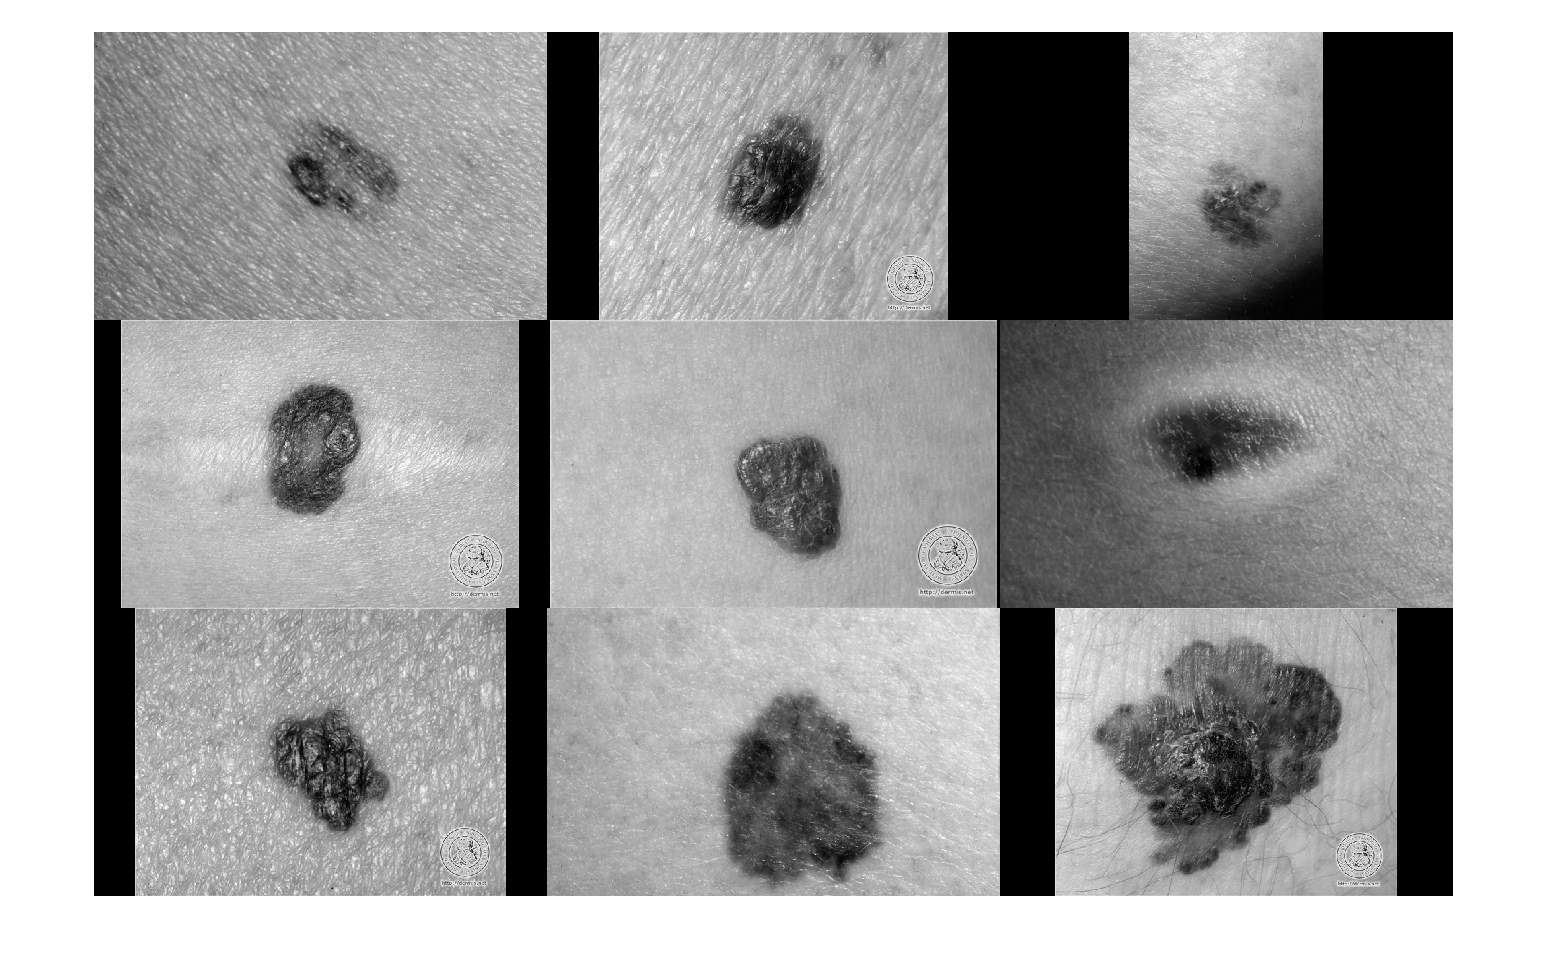

imds = imageDatastore(X_Train(1:9));
montage(imds)

trainds = augmentedImageDatastore([224 224],trainingData);
validds = augmentedImageDatastore([224 224],validData);
testds = augmentedImageDatastore([224 224],testingData);

layers = [
    imageInputLayer([224 224 1])
    convolution2dLayer(3,8,'Padding','same')
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,64,'Padding','same')
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,128,'Padding','same')
    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,256,'Padding','same')
    batchNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer];


options = trainingOptions("sgdm","MaxEpochs",150,"InitialLearnRate",0.0001,'Shuffle','every-epoch', ...
    'MiniBatchSize',64)

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 150
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'none'
                  SequenceLength:



% options = trainingOptions("sgdm","MaxEpochs",500,"InitialLearnRate",0.0001, ...
%     'ValidationData',{validds,YValid},'ValidationFrequency',10, ...
%     'MiniBatchSize',8,'Plots','training-progress')


% miniBatchSize  = 128;
% validationFrequency = floor(numel(YTrain)/miniBatchSize);
% options = trainingOptions('sgdm', ...
%     'MiniBatchSize',miniBatchSize, ...
%     'MaxEpochs',30, ...
%     'InitialLearnRate',1e-3, ...
%     'LearnRateSchedule','piecewise', ...
%     'LearnRateDropFactor',0.1, ...
%     'LearnRateDropPeriod',20, ...
%     'Shuffle','every-epoch', ...
%     'ValidationData',{testds,YTrain}, ...
%     'ValidationFrequency',validationFrequency, ...
%     'Plots','training-progress', ...
%     'Verbose',false);

ccnet = trainNetwork(trainds,layers,options)

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       117.78 |       6935.9 |      1.0000e-04 |
|       7 |          50 |       00:00:26 |        26.63 |        354.7 |      1.0000e-04 |
|      13 |         100 |       00:00:52 |        23.21 |        269.4 |      1.0000e-04 |
|      19 |         150 |       00:01:18 |        23.45 |        275.0 |      1.0000e-04 |
|      25 |         200 |       00:01:44 |        26.20 |        343.3 |      1.0000e-04 |
|      32 |         250 |       00:02:10 |        19.06 |        181.6 |      1.0000e-04 |
|      38 |         300 |  

ccnet =   SeriesNetwork with properties:

         Layers: [31×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


Train_Predicted = predict(ccnet,trainds);
Test_Predicted = predict(ccnet,testds);

Train_predictionError = Y_Train - Train_Predicted;
Test_predictionError = Y_Test - Test_Predicted;

Train_Pred_mae = errperf(Y_Train,Train_Predicted,'mae')

Train_Pred_mae = single
7.9450

Train_Pred_mse = errperf(Y_Train,Train_Predicted,'mse')

Train_Pred_mse = single
117.4010

Train_Pred_rmse = errperf(Y_Train,Train_Predicted,'rmse')

Train_Pred_rmse = single
10.8352

Train_Pred_mare = errperf(Y_Train,Train_Predicted,'mare')

Train_Pred_mare = single
0.0800

Train_Pred_msre = errperf(Y_Train,Train_Predicted,'msre')

Train_Pred_msre = single
0.0192

Train_Pred_rmsre = errperf(Y_Train,Train_Predicted,'rmsre')

Train_Pred_rmsre = single
0.1387

Train_Pred_mape = errperf(Y_Train,Train_Predicted,'mape')

Train_Pred_mape = single
8.0037

Train_Pred_mspe = errperf(Y_Train,Train_Predicted,'mspe')

Train_Pred_mspe = single
192.3590

Train_Pred_rmspe = errperf(Y_Train,Train_Predicted,'rmspe')

Train_Pred_rmspe = single
13.8694

Test_Pred_mae = errperf(Y_Test,Test_Predicted,'mae')

Test_Pred_mae = single
10.7982

Test_Pred_mse = errperf(Y_Test,Test_Predicted,'mse')

Test_Pred_mse = single
207.5436

Test_Pred_rmse = errperf(Y_Test,Test_Predicted,'rmse')

Test_Pred_rmse = single
14.4064

Test_Pred_mare = errperf(Y_Test,Test_Predicted,'mare')

Test_Pred_mare = single
0.0967

Test_Pred_msre = errperf(Y_Test,Test_Predicted,'msre')

Test_Pred_msre = single
0.0194

Test_Pred_rmsre = errperf(Y_Test,Test_Predicted,'rmsre')

Test_Pred_rmsre = single
0.1392

Test_Pred_mape = errperf(Y_Test,Test_Predicted,'mape')

Test_Pred_mape = single
9.6684

Testn_Pred_mspe = errperf(Y_Test,Test_Predicted,'mspe')

Testn_Pred_mspe = single
193.6572

Test_Pred_rmspe = errperf(Y_Test,Test_Predicted,'rmspe')

Test_Pred_rmspe = single
13.9161

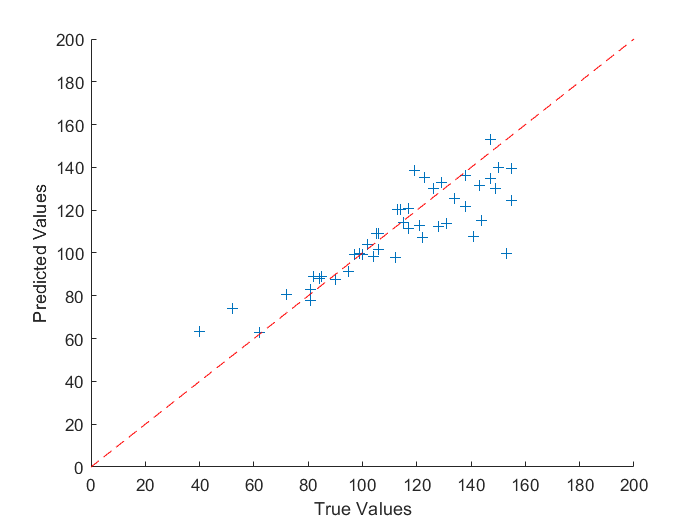

figure
scatter(Y_Test,Test_Predicted,'+')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 200], [0 200],'r--')

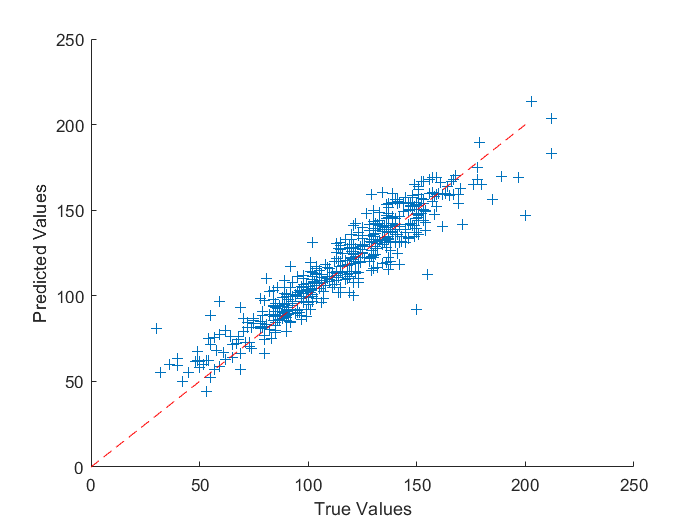

figure
scatter(Y_Train,Train_Predicted,'+')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 200], [0 200],'r--')


%ccnet.Layers